% mikeXcohen@gmail.com

## plot a sine wave

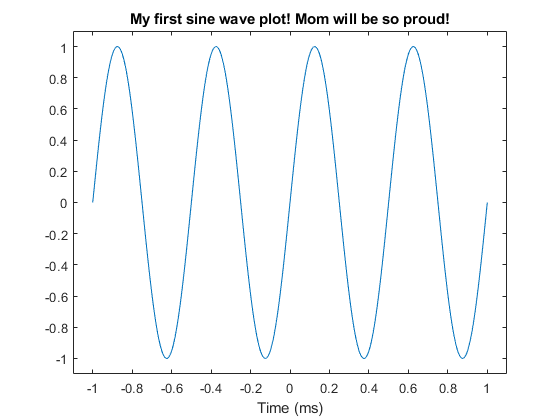

% define some variables
freq = 2;         % frequency in Hz
time = -1:.001:1; % -1 to 1 seconds in millisecond steps

% now create the sinewave
sinewaveDemo = 1*sin(2*pi*freq*time + 0);

% now plot it!
figure(1), clf
plot(time,sinewaveDemo)

% optional prettification of the plot
set(gca,'xlim',[-1.1 1.1],'ylim',[-1.1 1.1]); 
xlabel('Time (ms)')
title('My first sine wave plot! Mom will be so proud!')

## the sum of sine waves can appear like a complicated time series

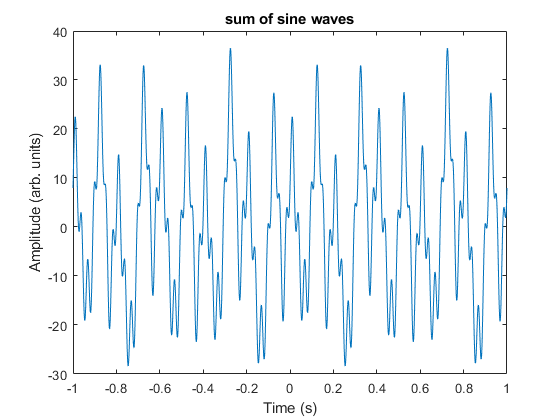

% create a few sine waves and sum

% define a sampling rate
srate = 1000;

% list some frequencies
frex = [ 3   10   5   15   35 ];

% list some random amplitudes... make sure there are the same number of
% amplitudes as there are frequencies!
amplit = [ 5   15   10   5   7 ];

% phases... list some random numbers between -pi and pi
phases = [  pi/7  pi/8  pi  pi/2  -pi/4 ];

% define time...
time = -1:1/srate:1;


% now we loop through frequencies and create sine waves
sine_waves = zeros(length(frex),length(time));
for fi=1:length(frex)
    sine_waves(fi,:) = amplit(fi) * sin(2*pi*time*frex(fi) + phases(fi));
end

% now plot the result
figure(2), clf
plot(time,sum(sine_waves))
title('sum of sine waves')
xlabel('Time (s)'), ylabel('Amplitude (arb. units)')

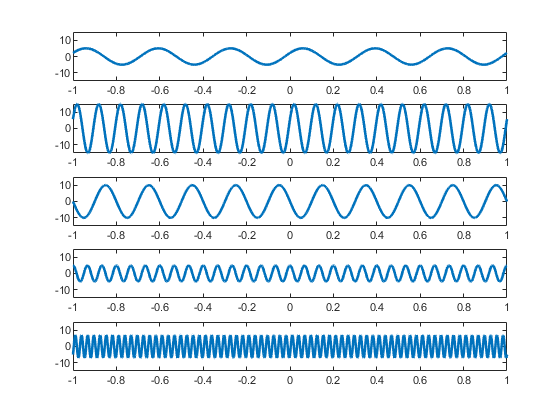



% now plot each wave separately
figure(3), clf
for fi=1:length(frex)
    subplot(length(frex),1,fi)
    plot(time, sine_waves(fi,:), 'LineWidth', 2)
    % to plot only one of these sine waves per iteration inside this loop
    axis([ time([1 end]) -max(amplit) max(amplit) ])
end

## Now compute Fourier representation of summed sine waves

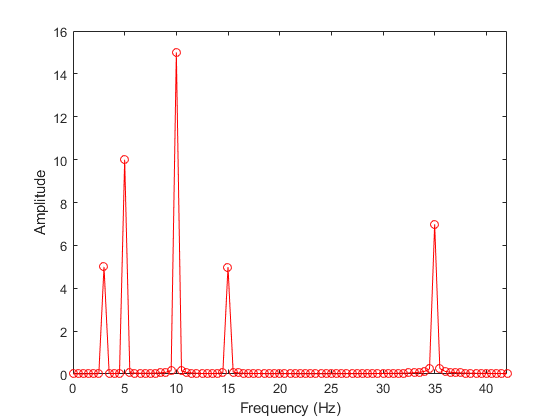

% take Fourier transform (via fast-Fourier transform)
sineX = fft( sum(sine_waves) )/length(time);

% define vector of frequencies in Hz
hz = linspace(0,srate/2,floor(length(time)/2)+1);

figure(4), clf
plot(hz,2*abs(sineX(1:length(hz))),'ro-')

% make the plot look a bit nicer
set(gca,'xlim',[0 max(frex)*1.2])
xlabel('Frequency (Hz)'), ylabel('Amplitude')

## end.